Detector = load("DetectorARMChallenge2.mat").Detector1;

realSense = realsenseSubscriberSO_ARM;

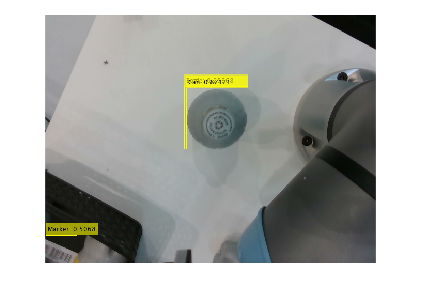

[colorImage,~] = realSense.step;
[bboxes, score, label] = detect(Detector, colorImage);

% Vizualizar
labelsWithScores = string(label) + ": " + string(score);
imTested = insertObjectAnnotation(colorImage, "rectangle", bboxes, labelsWithScores);
imshow(imTested);